clc;close all;clear;
load("data\system_parameters.mat");
addpath('inc\')
sympref("FloatingPointOutput",true);
% digits(2)

m_cuboid = 45e-3;
m_disk = 15e-3;
b = 40e-3;
c = 50e-3;
R = 40e-3;
d = 25e-3;
I0_cuboid = m_cuboid/12*(b^2+c^2);
I0_disk = 1/4*m_disk*R^2+m_disk*d^2; % Parallel Axis Theorem
I0 = I0_disk+I0_cuboid

I0 = 3.0750e-05

## Symbolic Dynamic Equations for Report

## Jacobians for each CG

syms q1 q2 q3 q4 real
syms q1_d q2_d q3_d q4_d real
syms q1_dd q2_dd q3_dd q4_dd real
q = {q1,q2,q3,q4};
q_d = {q1_d,q2_d,q3_d,q4_d};
q_dd = {q1_dd,q2_dd,q3_dd,q4_dd};

% T = fwdKin([q1;q2;q3;q4],p);
load("data\fwdKin_symbolic.mat")
T = subs(T,{'theta_1','theta_2','theta_3','theta_4'},q)

T = struct with fields:
    T10: [4×4 sym]
    T21: [4×4 sym]
    T32: [4×4 sym]
    T43: [4×4 sym]
    T54: [4×4 sym]
    T20: [4×4 sym]
    T30: [4×4 sym]
    T40: [4×4 sym]
    T50: [4×4 sym]



cg11 = [0;-20e-3;0];
cg10 = T.T10*[cg11; 1];
cg10 = cg10(1:3);
J1 = jac(cg10,T);
J1(:,2:end) = 0;

cg22 = [-30e-3;0;0];
cg20 = T.T20*[cg22; 1];
cg20 = cg20(1:3);
J2 = jac(cg20,T);
J2(:,3:end) = 0;
simplify(J2);

cg33 = [-30e-3;0;0];
cg30 = T.T30*[cg33; 1];
cg30 = cg30(1:3);
J3 = jac(cg30,T);
J3(:,4:end) = 0;
simplify(J3);

cg44 = [-25e-3;15e-3;0];
cg40 = T.T40*[cg44; 1];
cg40 = cg40(1:3);
J4 = jac(cg40,T);
simplify(J4);

cg = {cg10,cg20,cg30,cg40};


## Inertia Matrix D(q)

m = {60e-3 80e-3 80e-3 40e-3};
Jv = {J1(1:3,:),J2(1:3,:),J3(1:3,:),J4(1:3,:)};
Jw = {J1(4:6,:),J2(4:6,:),J3(4:6,:),J4(4:6,:)};
R = {T.T10(1:3,1:3),T.T20(1:3,1:3),T.T30(1:3,1:3),T.T40(1:3,1:3)};

I1 = diag([I0 0.4*I0 0.9*I0]);
I2 = diag([0.45*I0 1.4*I0 1.2*I0]);
I3 = I2;
I4 = diag([0.5*I0 0.5*I0 0.5*I0]);

I = {I1,I2,I3,I4};

D = zeros(4);
for i = 1:4
    D = D + m{i}*Jv{i}'*Jv{i}+Jw{i}'*R{i}*I{i}*R{i}*Jw{i};
end
% D = reshape(simplify(D),[16,1]);
% 
% % =========== Clean up spurious coefficients ===========
% 
% for i = 1:length(D)
%     Coef = coeffs(D(i));
%     for j = 1:length(Coef)
%         if abs(Coef(j)) < 1e-6 %you can change 0.001 to adjust precision
%             D(i) = subs(D(i),Coef(j),0);
%         end
%     end
% end
% 
% D = reshape(D,[4,4])
D = simplify(D)

$$D = \begin{array}{l} \left(\begin{array}{cccc} 2.8444e-05\,\sigma_{7}-1.4606e-05\,\sin\left(q_{1}-q_{2}\right)-1.0846e-04\,\cos\left(2\,q_{2}+2\,q_{3}+q_{4}+0.5404\right)-8.1468e-04\,\cos\left(2\,q_{2}+q_{3}\right)-6.7770e-04\,\cos\left(2\,q_{2}\right)-3.3174e-04\,\sigma_{3}+\sigma_{9}-1.7000e-05\,\cos\left(2\,q_{2}+2\,q_{3}+2\,q_{4}+1.0808\right)+1.4606e-05\,\sin\left(q_{2}-q_{1}+q_{3}\right)+\sigma_{8}+2.8444e-05\,\sin\left(q_{1}+q_{2}\right)-1.0846e-04\,\cos\left(2\,q_{2}+q_{3}+q_{4}+0.5404\right)-1.2300e-05\,\cos\left(q_{1}\right)+8.1468e-04\,\cos\left(q_{3}\right)+1.0846e-04\,\sigma_{10}+0.0010 & \sigma_{1}-1.4606e-05\,\cos\left(2\,q_{1}\right)-7.3031e-06\,\cos\left(2\,q_{2}\right)+\sigma_{2}+1.4222e-05\,\cos\left(2\,q_{1}+2\,q_{2}\right)-7.3031e-06\,\sigma_{3}+3.6131e-05 & \sigma_{1}-7.3031e-06\,\cos\left(2\,q_{1}\right)+\sigma_{2}-7.3031e-06\,\sigma_{3}+2.1909e-05 & \sigma_{1}+7.6875e-06\\ 0 & 3.6900e-05\,\sigma_{7}+\sigma_{6}+\sigma_{8}+3.6900e-05\,\sin\left(q_{1}+q_{2}\right)+0.0016\,\cos\left(q_{3}\right)+2.1691e-04\,\sigma_{10}+0.0021 & \sigma_{4} & \sigma_{5}\\ 0 & \sigma_{4} & 3.6900e-05\,\sigma_{7}+\sigma_{6}+\sigma_{8}+6.9748e-04 & \sigma_{9}+\sigma_{8}+3.4000e-05\\ 0 & \sigma_{5} & \sigma_{9}+\sigma_{8}+3.4000e-05 & \sigma_{8}+3.4000e-05 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=7.6875e-06\,\cos\left(2\,q_{1}+2\,q_{2}+2\,q_{3}+2\,q_{4}\right)\\ \sigma_{2}=1.4222e-05\,\cos\left(2\,q_{1}+2\,q_{2}+2\,q_{3}\right)\\ \sigma_{3}=\cos\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{4}=3.6900e-05\,\sigma_{7}+\sigma_{6}+\sigma_{8}+8.1468e-04\,\cos\left(q_{3}\right)+1.0846e-04\,\sigma_{10}+6.9748e-04\\ \sigma_{5}=\sigma_{9}+\sigma_{8}+1.0846e-04\,\sigma_{10}+3.4000e-05\\ \sigma_{6}=2.1691e-04\,\cos\left(q_{4}+0.5404\right)\\ \sigma_{7}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{8}=1.5375e-05\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{9}=1.0846e-04\,\cos\left(q_{4}+0.5404\right)\\ \sigma_{10}=\cos\left(q_{3}+q_{4}+0.5404\right) \end{array}$$

## Christoffel Terms

C = sym(zeros(4));

for k = 1:4 % k'th joint
    for j = 1:4
        for i = 1:4
            C(k,j) = C(k,j) + 0.5*(diff(D(k,j),q{i}) + diff(D(k,i),q{j}) - diff(D(i,i),q{k}))*q_d{i};
        end
    end
end
simplify(C);


## Potential Matrix

P = 0;
for k = 1:4
    P = P - m{k}*[0;0;-9.81]'*cg{k};
end

for k = 1:4
    g(k,1) = diff(P,q{k});
end

## Joint Torques along Polynomial Path

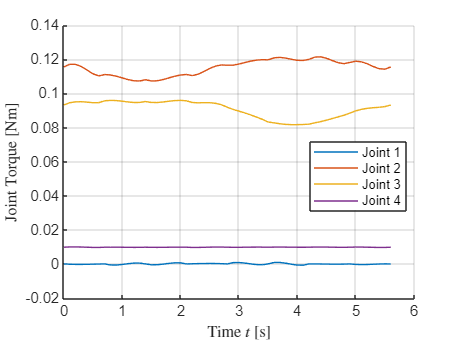

load("data\trajectory_jointSpace_10points.mat");
q = qAB_10; clear qAB_10;
q_d = qAB_10_d; clear qAB_10_d;
q_dd = qAB_10_dd; clear qAB_10_dd;

for i = 1:length(q)
    tau(:,i) = invDyn(q(:,i),q_d(:,i),q_dd(:,i));
end

dt = 0.1;

figure;
hold on
plot(0:dt:(length(tau)-1)*dt,tau);
ylabel("Joint Torque [Nm]",'Interpreter','latex')
xlabel("Time $t$ [s]",'Interpreter','latex')
legend("Joint 1","Joint 2","Joint 3","Joint 4")
grid on
legend(["Joint 1", "Joint 2", "Joint 3", "Joint 4"], "Position", [0.6794 0.3871 0.2096, 0.1977])